# 【Final Project】only 1 person Zi-An Lee

I want to explore the changes in electricity generation methods, amounts, emissions, and efficiency in the United States over the years. 

 I want to do a project of comparing the change in ways electricity is generated over the years.  Different generation methods and different fuels such as solar, nuclear, wind, coal, petroleum, and hydro can lead to different environmental effects. I want to look at the generation amount and the environmental effects such as emissions.

I want to investigate whether or not the proportions of electricity generation by renewable sources has increased over the years and whether the use of fossil fuels have decreased.

I also want to see whether or not the emissions such as carbon dioxide, sulfur dioxide, and nitrogen oxide due to electricity generation has been decreasing both in terms of emissions per unit of electricity generation and emissions overall/total.

I also want to look at the useful thermal output produced throughout the years during electricity generation and see which sources are the best at producing both electricity and useful heat that can be used for heating/cooling at the same time. I also want to see if they have been getting better and more efficient at capturing and reusing heat created during electricity generation over the past 11 years.

I will be using datasets from the Energy Information Administration [https://www.eia.gov/electricity/data.php](https://www.eia.gov/electricity/data.php)

First, we need to load the datasets and save them into variables.

epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors = readtable('epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors.xlsx')

epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors = 52×16 table
          Var1           GenerationAtUtilityScaleFacilities    Var3     Var4        Var5       Var6        Var7          Var8          Var9         Var10       Var11    Var12      Var13       SmallScaleGeneration    NetGenerationFromUtilityAndSmallScaleFacilities      Var16   
    _________________    __________________________________    _____    _____    __________    _____    __________    __________    __________    __________    _____    _____

epa_03_01_bByTypeOfRenewableSourceAllSectors=readtable('epa_03_01_bByTypeOfRenewableSourceAllSectors.xlsx')

epa_03_01_bByTypeOfRenewableSourceAllSectors = 52×14 table
          Var1           GenerationAtUtilityScaleFacilities       Var3       Var4    Var5     Var6     Var7    Var8    Var9       Var10         Var11       SmallScaleGeneration    GenerationFromUtilityAndSmallScaleFacilities      Var14   
    _________________    __________________________________    __________    ____    _____    _____    ____    ____    _____    __________    __________    ____________________    ____________________________________________    _______

epa_03_23UsefulThermalOutputByEnergySourceAndTypeOfCombinedHeatAndPowerProducersAllSectors=readtable('epa_03_23UsefulThermalOutputByEnergySourceAndTypeOfCombinedHeatAndPowerProducersAllSectors.xlsx')

epa_03_23UsefulThermalOutputByEnergySourceAndTypeOfCombinedHeatAndPowerProducersAllSectors = 52×9 table
         Period             Coal       PetroleumLiquids    PetroleumCoke    NaturalGas    OtherFossilGas    RenewableSources    Other      Total   
    _________________    __________    ________________    _____________    __________    ______________    ________________    _____    __________

    {'Annual Totals'}           NaN           NaN                NaN               NaN             NaN                NaN         NaN           NaN
    {'2014'         }    2.3251e+05         11990              23457        5.4562e+05      1.0487e+05         6.2409e+05       21390    1.5639e+

epa_09_01EmissionsFromEnergyConsumptionAtPowerPlants=readtable('epa_09_01EmissionsFromEnergyConsumptionAtPowerPlants')

epa_09_01EmissionsFromEnergyConsumptionAtPowerPlants = 12×4 table
    Year    CarbonDioxide_CO2_    SulfurDioxide_SO2_    NitrogenOxides_NOx_
    ____    __________________    __________________    ___________________

    2014        2.1683e+06               3454                  2100        
    2015        2.0315e+06               2548                  1824        
    2016        1.9284e+06               1807                  1630        
    2017        1.8498e+06               1599                  1493        
    2018        1.8723e+06               1517                  1474        
    2019        1.7249e+06               1267                  1342        
    2020        1.5536e+06               1023                  1211        
    2021        1.6519e+06               1168                  1253        
    2022        1.6504e+06           

In order to calculate the total electricity generation in the United States each year from 2014 to 2024,  first we have to extract/save the yearly totals of electricity generation at utility scale facilities as a vector.

totalUtilScaleGen=epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors.Var13(2:12)

totalUtilScaleGen =      4093564
     4078714
     4077574
     4035443
     4180988
     4130574
     4009767
     4109699
     4230668
     4183270
     4308634


Next, we have to extract/save the yearly totals of electricity generation at small scale facilities as a vector.

smallScaleGen=epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors.SmallScaleGeneration(2:12)

smallScaleGen =        11233
       14139
       18812
       23990
       29539
       34957
       41522
       49164
       61282
       73406
       83918


Next, we add up the 2 vectors to get a vector containing the total electricity generation in the United States for each year.

totalGeneration=totalUtilScaleGen+smallScaleGen

totalGeneration =      4104797
     4092853
     4096386
     4059433
     4210527
     4165531
     4051289
     4158863
     4291950
     4256676
     4392552


I will need to create a vector containg the years for plotting.

Years=[2014, 2015, 2016, 2017, 2018, 2019, 2020, 2021, 2022, 2023, 2024]

Years =         2014        2015        2016        2017        2018        2019        2020        2021        2022        2023        2024


I want to compare the electricity generation using renewable sources to the total generation over the years. 

Electricity generation using renewable sources is more sustainable and has a positive impact on the environment. It can reduce long term energy expenses and also reduce fossil fuel usage. It can require less consumption of resources and also produce less pollution and emissions.

To find the total electricity generation using renewable sources for each year we first have to extract /save the yearly totals of electricity generation using renewable sources at utility scale facilities as a vector.

totalRenewableUtilScaleGen=epa_03_01_bByTypeOfRenewableSourceAllSectors.Var11(2:12)

totalRenewableUtilScaleGen =       538579
      544241
      609445
      686583
      706816
      728673
      783012
      815267
      900814
      895241
      976463


Next, we have to extract the yearly totals of electricity generation using renewable sources at small scale facilities as a vector.

renewableSmallScaleGen=epa_03_01_bByTypeOfRenewableSourceAllSectors.SmallScaleGeneration(2:12)

renewableSmallScaleGen =        11233
       14139
       18812
       23990
       29539
       34957
       41522
       49164
       61282
       73406
       83918


Next, we add them together.

totalRenewableGeneration=totalRenewableUtilScaleGen+renewableSmallScaleGen

totalRenewableGeneration =       549812
      558380
      628257
      710573
      736355
      763630
      824534
      864431
      962096
      968647
     1060381


I want to make a plot to compare electricity generation by renewable sources and total generation.

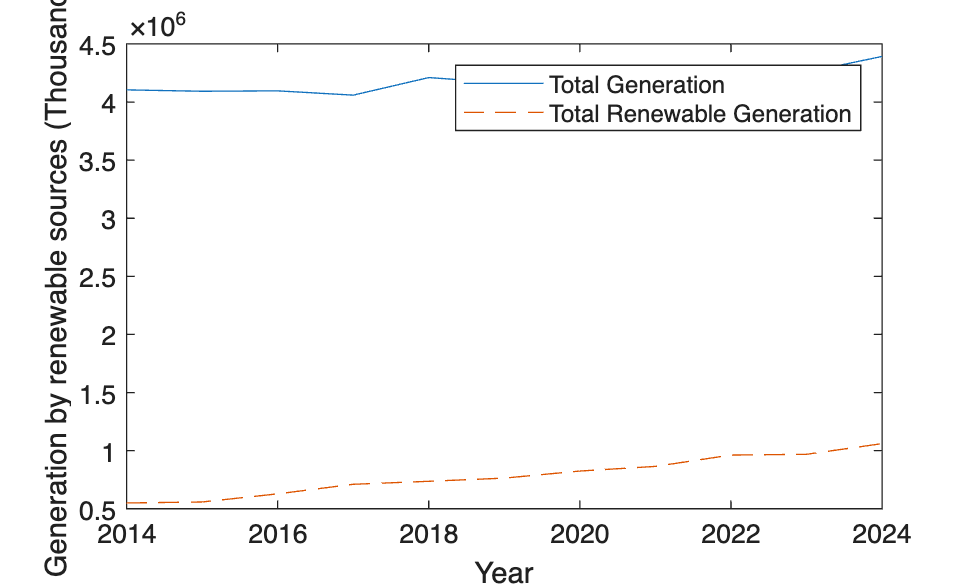

plot(Years, totalGeneration)
hold on
plot(Years, totalRenewableGeneration, '--')
xlabel('Year')
ylabel('Total Generation by renewable sources (Thousand MWh)')

legend('Total Generation', 'Total Renewable Generation')
hold off

It seems that generation by renewable sources has only been a small part of the total electricity generation. We can also see from the graph that electricity usage has been increasing steadily over the years.

I want to find and compare the gap between electricity generation by renewable sources and total generation by finding the difference for each year and plotting.

Do subtraction to find the gap for each year.

gap=totalGeneration-totalRenewableGeneration

gap =      3554985
     3534473
     3468129
     3348860
     3474172
     3401901
     3226755
     3294432
     3329854
     3288029
     3332171


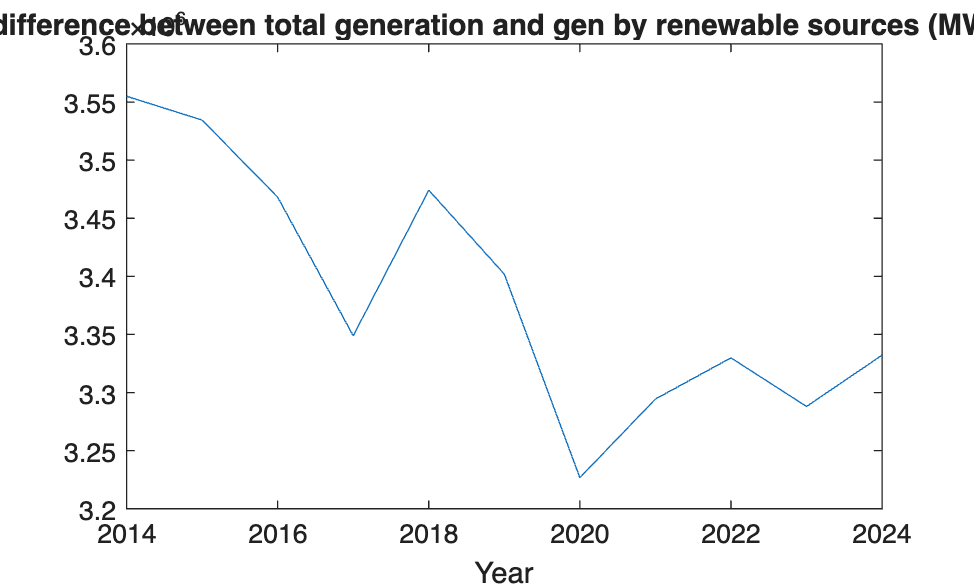


plot(Years,gap)

xlabel('Year')
title('difference between total generation and gen by renewable sources (MWh)')

It seems from the plot that the difference between total electricity generation and generation by renewable sources has fluctuated over the past ten years but has greatly decreased and is generally decreasing. This is supposed to benefit the environment.

I want to find and compare the ratio of renewable generation to total generation over the years and make a plot.

Divide to find the ratio for each year

ratio=totalRenewableGeneration./totalGeneration

ratio =     0.1339
    0.1364
    0.1534
    0.1750
    0.1749
    0.1833
    0.2035
    0.2079
    0.2242
    0.2276
    0.2414


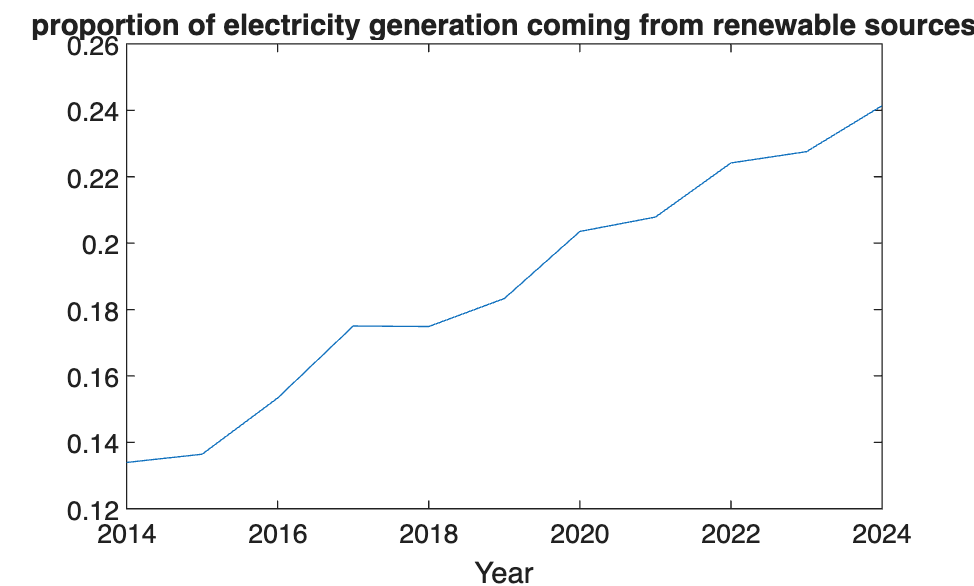

plot(Years,ratio)

xlabel('Year')
title('proportion of electricity generation coming from renewable sources')

It seems from the plot that the percentage of total electricity generation by renewable sources has greatly increased over the past 10 years and has been on a steady increasing trend. This is supposed to be good for the environment.

For the next part, I have to first extract/save the total electricity generation by each type of resource for the past 10 years.

coalGen=epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors.GenerationAtUtilityScaleFacilities(2:12)

coalGen =      1581710
     1352398
     1239149
     1205835
     1149487
      964957
      773393
      897999
      831512
      675115
      652156


petroleumLiquidsGen=epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors.Var3(2:12)

petroleumLiquidsGen =        18276
       17372
       13008
       12414
       16245
       11522
        9662
       11663
       15805
       11397
       11456


petroleumCokeGen=epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors.Var4(2:12)

petroleumCokeGen =        11955
       10877
       11197
        8976
        8981
        6819
        7679
        7511
        7126
        4836
        3629


naturalGasGen=epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors.Var5(2:12)

naturalGasGen =      1126635
     1334668
     1379271
     1297703
     1471843
     1588533
     1626790
     1579190
     1687065
     1806063
     1869902


otherFossilGasGen=epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors.Var6(2:12)

otherFossilGasGen =        12022
       13117
       12807
       12469
       13463
       12591
       11818
       11397
       11722
       11778
       10845



nuclearGen=epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors.Var7(2:12)

nuclearGen =       797166
      797178
      805694
      804950
      807084
      809409
      789879
      779645
      771537
      774873
      781865


hydroElectricConventionalGen=epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors.Var8(2:12)

hydroElectricConventionalGen =       259367
      249080
      267812
      300333
      292524
      287874
      285274
      251585
      254789
      245002
      242896


solarGen=epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors.Var9(2:12)

solarGen =        17691
       24893
       36054
       53287
       63825
       71937
       89199
      115258
      143792
      165530
      219834


renewableExcludingHydroElectricAndSolarGen=epa_03_01_aByAllEnergySourcesAndByProducingSectorAllSectors.Var10(2:12)

renewableExcludingHydroElectricAndSolarGen =       261522
      270268
      305579
      332963
      350467
      368862
      408539
      448424
      502234
      484708
      513733


We want to find and compare the change (in amount) of both renewable generation of each type and non renewable generation of each type for each year compared to the previous year.

We need to use the diff function.

Years2=[2015, 2016, 2017, 2018, 2019, 2020, 2021, 2022, 2023, 2024]

Years2 =         2015        2016        2017        2018        2019        2020        2021        2022        2023        2024


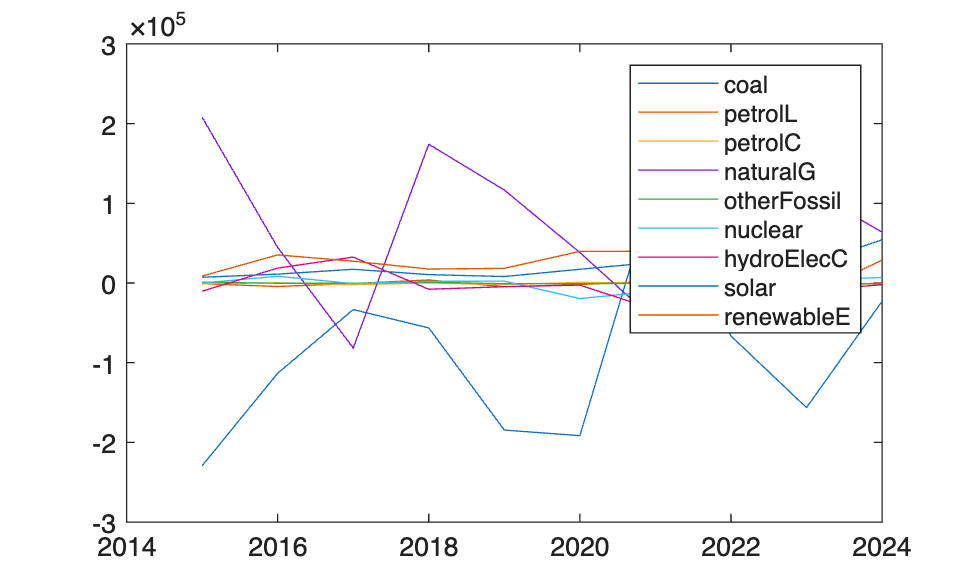

plot(Years2, diff(coalGen))
hold on
plot(Years2, diff(petroleumLiquidsGen))
plot(Years2, diff(petroleumCokeGen))
plot(Years2, diff(naturalGasGen))
plot(Years2, diff(otherFossilGasGen))

plot(Years2, diff(nuclearGen))
plot(Years2, diff(hydroElectricConventionalGen))
plot(Years2, diff(solarGen))
plot(Years2, diff(renewableExcludingHydroElectricAndSolarGen))
legend('coal', 'petrolL', 'petrolC', 'naturalG', 'otherFossil', 'nuclear', 'hydroElecC', 'solar', 'renewableE')
hold off

It seems that coal has the biggest increases and decrease, fluctuating between positive change and negative change. It seems that other fossil fuels have been consistently decreasing from year to year but fluctuating greatly by the amount of decrease.

Generation and useful thermal output

Useful thermal output during electricity production is when the heat created during some processes required for electricity generation is reused for many purposes.

We need to first extract/save the useful thermal outputs produced by each type of resource for each year during electricity production

coalThermalOutput=epa_03_23UsefulThermalOutputByEnergySourceAndTypeOfCombinedHeatAndPowerProducersAllSectors.Coal(2:12)

coalThermalOutput =       232509
      211030
      220162
      193164
      182373
      162108
      139423
      149948
      146782
      121382
      114656


petroleumLiquidsThermalOutput=epa_03_23UsefulThermalOutputByEnergySourceAndTypeOfCombinedHeatAndPowerProducersAllSectors.PetroleumLiquids(2:12)

petroleumLiquidsThermalOutput =        11990
       11796
        8607
        7922
        9878
        7992
        6463
        7603
       16516
       12155
        8211


petroleumCokeThermalOutput=epa_03_23UsefulThermalOutputByEnergySourceAndTypeOfCombinedHeatAndPowerProducersAllSectors.PetroleumCoke(2:12)

petroleumCokeThermalOutput =        23457
       21748
       20122
       17322
       16581
       14278
       12359
       12390
       11793
        9979
       10262


naturalGasThermalOutput=epa_03_23UsefulThermalOutputByEnergySourceAndTypeOfCombinedHeatAndPowerProducersAllSectors.NaturalGas(2:12)

naturalGasThermalOutput =       545624
      591749
      785413
      789485
      813127
      802153
      835666
      818647
      805556
      810007
      835189


otherFossilGasThermalOutput=epa_03_23UsefulThermalOutputByEnergySourceAndTypeOfCombinedHeatAndPowerProducersAllSectors.OtherFossilGas(2:12)

otherFossilGasThermalOutput =       104868
       98910
      148881
      151579
      172677
      142229
      135048
      135509
      133148
      143075
      146260



renewableSourcesThermalOutput=epa_03_23UsefulThermalOutputByEnergySourceAndTypeOfCombinedHeatAndPowerProducersAllSectors.RenewableSources(2:12)

renewableSourcesThermalOutput =       624086
      626887
      698858
      674248
      663644
      643548
      602034
      609495
      587576
      541688
      532926




totalThermalOutput=epa_03_23UsefulThermalOutputByEnergySourceAndTypeOfCombinedHeatAndPowerProducersAllSectors.Total(2:12)

totalThermalOutput =      1563923
     1581849
     1907384
     1857405
     1881448
     1794736
     1751893
     1753188
     1719846
     1657377
     1666236


To find the total thermal output from generation by non renewable sources, we do addition and add up the values for the individuals.

totalNonRenewableThermalOutput=coalThermalOutput+petroleumLiquidsThermalOutput+petroleumCokeThermalOutput+naturalGasThermalOutput+otherFossilGasThermalOutput

totalNonRenewableThermalOutput =       918448
      935233
     1183185
     1159472
     1194636
     1128760
     1128959
     1124097
     1113795
     1096598
     1114578


We plot it

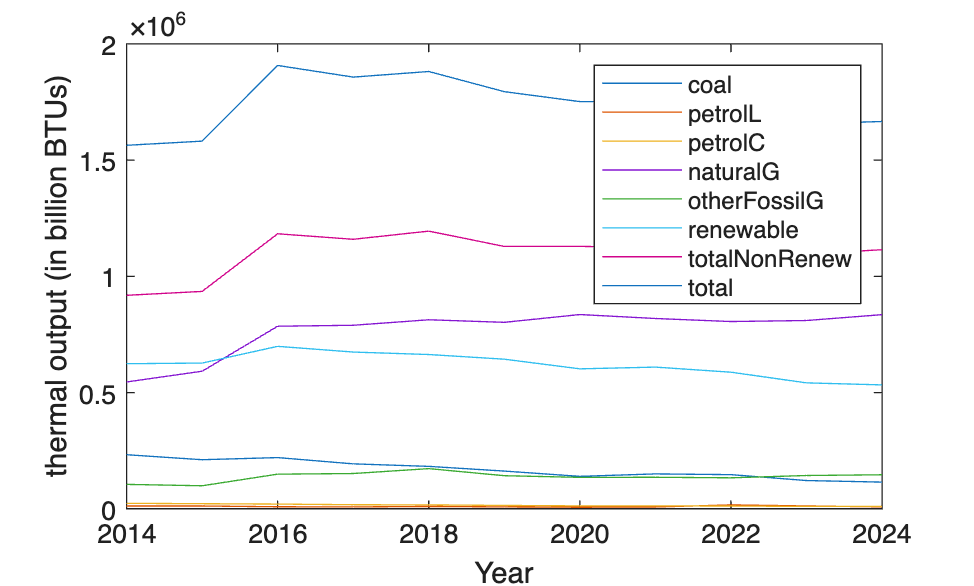


plot(Years,coalThermalOutput)
hold on
plot(Years,petroleumLiquidsThermalOutput)
plot(Years,petroleumCokeThermalOutput)
plot(Years,naturalGasThermalOutput)
plot(Years,otherFossilGasThermalOutput)

plot(Years,renewableSourcesThermalOutput)

plot(Years, totalNonRenewableThermalOutput)

plot(Years, totalThermalOutput)

xlabel('Year')
ylabel('thermal output (in billion BTUs)')

legend('coal', 'petrolL', 'petrolC', 'naturalG', 'otherFossilG', 'renewable', 'totalNonRenew', 'total')
hold off

Combined heat and power systems can be more efficient than generating power and heat separately. The heat created during electricity generation can be used for steam production, which can then be used for heating. The waste heat can also be used to produce chilled water for cooling systems.

We want find the ratio of useful thermal output to amount of electricity generation using different sources.

We need to use ./ to do division between the values of the useful thermal output vector of each type and the electricity generation vector of each type.

coalUsefulThermalRatio=coalThermalOutput./coalGen

coalUsefulThermalRatio =     0.1470
    0.1560
    0.1777
    0.1602
    0.1587
    0.1680
    0.1803
    0.1670
    0.1765
    0.1798
    0.1758


petroleumLiquidsUsefulThermalRatio=petroleumLiquidsThermalOutput./petroleumLiquidsGen

petroleumLiquidsUsefulThermalRatio =     0.6561
    0.6790
    0.6617
    0.6382
    0.6081
    0.6936
    0.6689
    0.6519
    1.0450
    1.0665
    0.7167


petroleumCokeUsefulThermalRatio=petroleumCokeThermalOutput./petroleumCokeGen

petroleumCokeUsefulThermalRatio =     1.9621
    1.9994
    1.7971
    1.9298
    1.8462
    2.0939
    1.6095
    1.6496
    1.6549
    2.0635
    2.8278


naturalGasUsefulThermalRatio=naturalGasThermalOutput./naturalGasGen

naturalGasUsefulThermalRatio =     0.4843
    0.4434
    0.5694
    0.6084
    0.5525
    0.5050
    0.5137
    0.5184
    0.4775
    0.4485
    0.4466


otherFossilGasUsefulThermalRatio=otherFossilGasThermalOutput./otherFossilGasGen

otherFossilGasUsefulThermalRatio =     8.7230
    7.5406
   11.6250
   12.1565
   12.8260
   11.2961
   11.4273
   11.8899
   11.3588
   12.1476
   13.4864



renewableSourcesUsefulThermalRatio=renewableSourcesThermalOutput./totalRenewableUtilScaleGen

renewableSourcesUsefulThermalRatio =     1.1588
    1.1519
    1.1467
    0.9820
    0.9389
    0.8832
    0.7689
    0.7476
    0.6523
    0.6051
    0.5458


I need to plot.

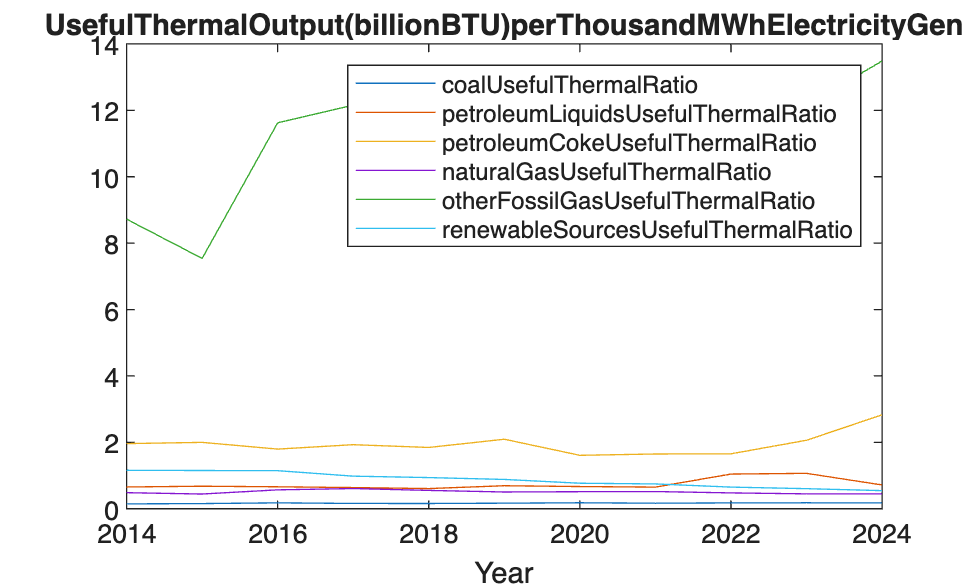


plot(Years,coalUsefulThermalRatio)
hold on
plot(Years,petroleumLiquidsUsefulThermalRatio)
plot(Years,petroleumCokeUsefulThermalRatio)
plot(Years,naturalGasUsefulThermalRatio)
plot(Years,otherFossilGasUsefulThermalRatio)

plot(Years,renewableSourcesUsefulThermalRatio)

xlabel('Year')
title('UsefulThermalOutput(billionBTU)perThousandMWhElectricityGen')

legend('coalUsefulThermalRatio', 'petroleumLiquidsUsefulThermalRatio', 'petroleumCokeUsefulThermalRatio', 'naturalGasUsefulThermalRatio', 'otherFossilGasUsefulThermalRatio', 'renewableSourcesUsefulThermalRatio')
hold off

I think that having a higher useful thermal output for each thousand MWh of electricity production can mean that a higher percentage of waste heat produced is being captured and used which is means greater efficiency. The graph seems to show that other fossil gases has the highest ratio of waste heat reuseal for each unit of electricity generation. This could mean that it is easier to capture heat during electricity generation using this particular resource, or maybe it just generates more heat than all the other resources.

Emissions from energy consumption at power plants

First, we need to save the emission amounts over the years for each type of emissions in separate variables.

CarbonDioxideEmissions=epa_09_01EmissionsFromEnergyConsumptionAtPowerPlants.CarbonDioxide_CO2_(1:11)

CarbonDioxideEmissions =      2168284
     2031452
     1928401
     1849750
     1872330
     1724873
     1553586
     1651911
     1650367
     1531554
     1537073


SulfurDioxideEmissions=epa_09_01EmissionsFromEnergyConsumptionAtPowerPlants.SulfurDioxide_SO2_(1:11)

SulfurDioxideEmissions =         3454
        2548
        1807
        1599
        1517
        1267
        1023
        1168
        1079
         848
         808


NitrogenOxidesEmissions=epa_09_01EmissionsFromEnergyConsumptionAtPowerPlants.NitrogenOxides_NOx_(1:11)

NitrogenOxidesEmissions =         2100
        1824
        1630
        1493
        1474
        1342
        1211
        1253
        1230
        1117
        1112


Carbon dioxide emissions can cause climate change and many negative effects so it is best to reduce it as much as possible.

Sulfur dioxide can be emitted during burning fossil fuels for electricity generation. This sulfur dioxide can irritate people's breathing systems, cause acid rain, and do much damage.

Increasing nitrogen oxide can also make breathing problems and acid rain.

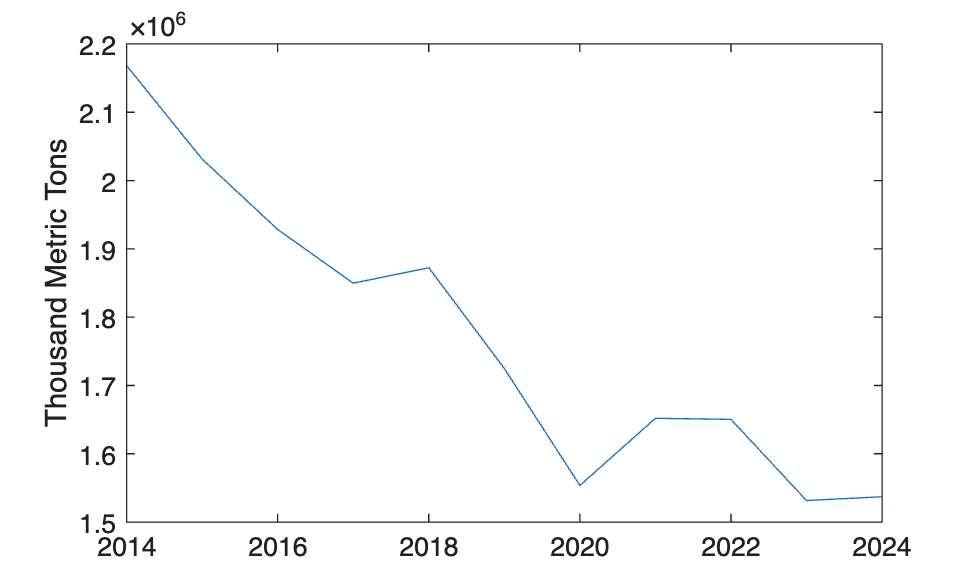

plot(Years,CarbonDioxideEmissions)
ylabel('Thousand Metric Tons')

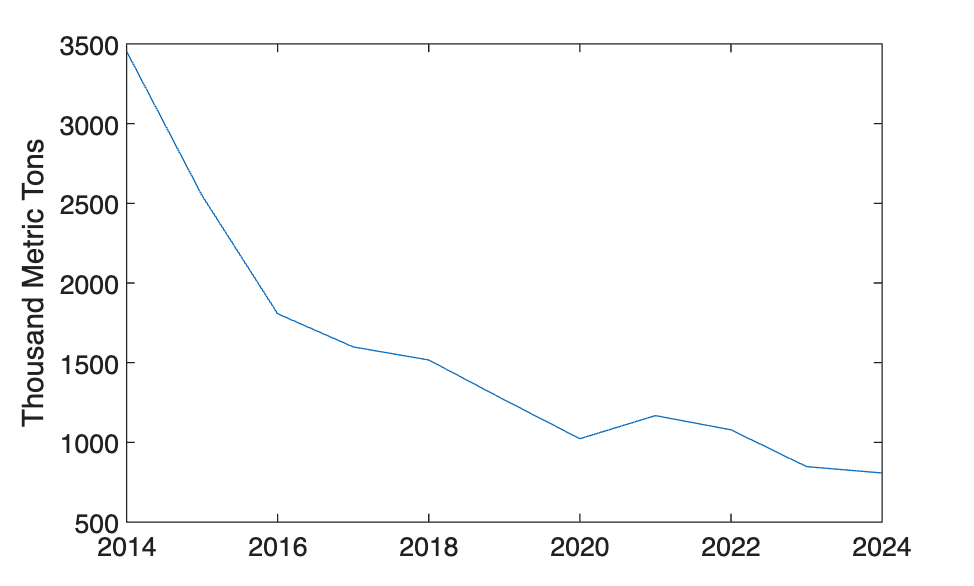

plot(Years,SulfurDioxideEmissions)
ylabel('Thousand Metric Tons')

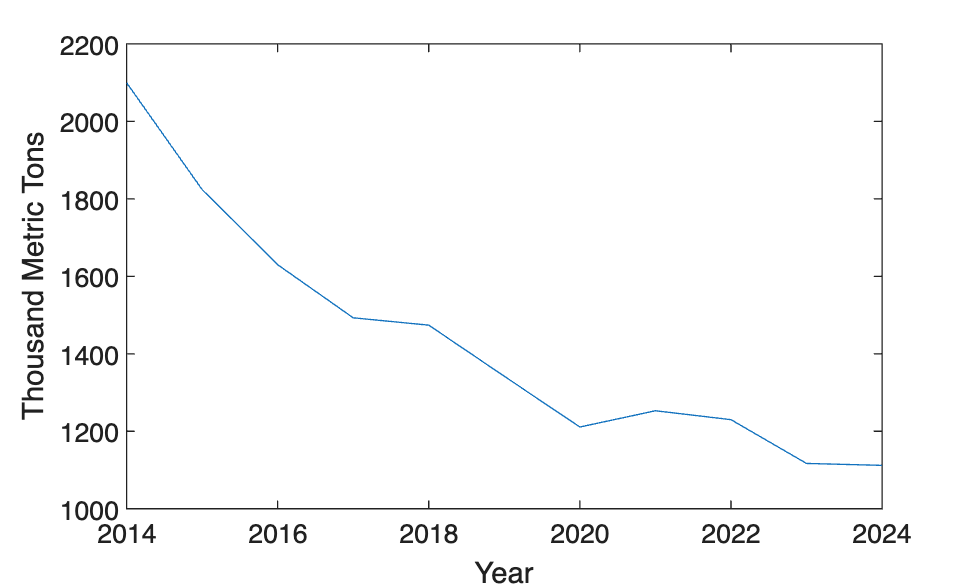

plot(Years,NitrogenOxidesEmissions)

xlabel('Year')
ylabel('Thousand Metric Tons')

We want compare the emissions from year to year with the amount of generation. 

I want to do ratio of emissions to generation for each year.

Which one increases faster?     is the emissions of each unit of electricity generation decreasing over the years?

I need to use ./ to divide the elements of the emissions vectors by elements of the total generation vector

CarbonDioxideEfficiency=CarbonDioxideEmissions./totalGeneration

CarbonDioxideEfficiency =     0.5282
    0.4963
    0.4708
    0.4557
    0.4447
    0.4141
    0.3835
    0.3972
    0.3845
    0.3598
    0.3499



SulfurDioxideEfficiency=SulfurDioxideEmissions./totalGeneration

SulfurDioxideEfficiency = 1.0e-03 *

    0.8415
    0.6225
    0.4411
    0.3939
    0.3603
    0.3042
    0.2525
    0.2808
    0.2514
    0.1992
    0.1839



NitrogenOxidesEfficiency=NitrogenOxidesEmissions./totalGeneration

NitrogenOxidesEfficiency = 1.0e-03 *

    0.5116
    0.4457
    0.3979
    0.3678
    0.3501
    0.3222
    0.2989
    0.3013
    0.2866
    0.2624
    0.2532


Then I need to plot or graph.

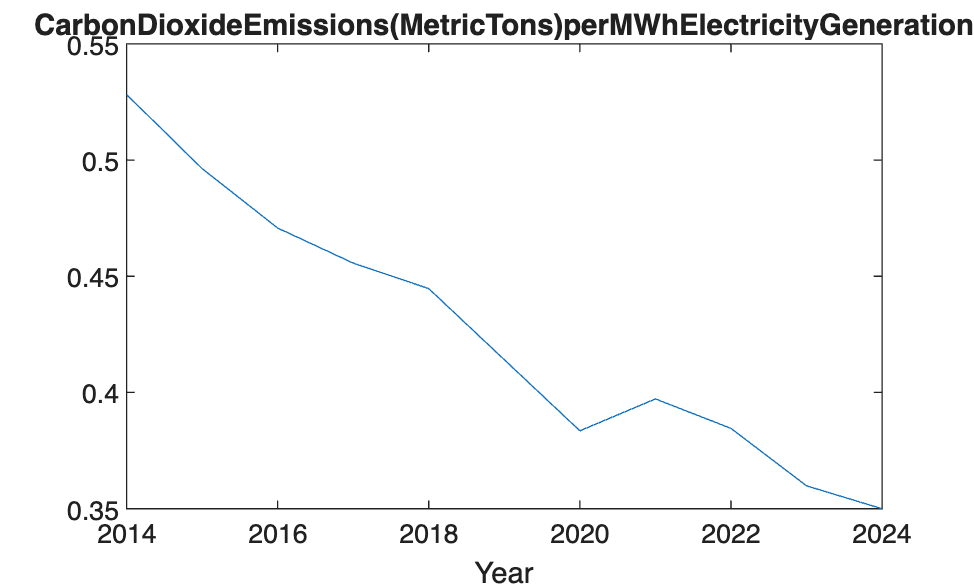

plot(Years,CarbonDioxideEfficiency)

xlabel('Year')
title('CarbonDioxideEmissions(MetricTons)perMWhElectricityGeneration')

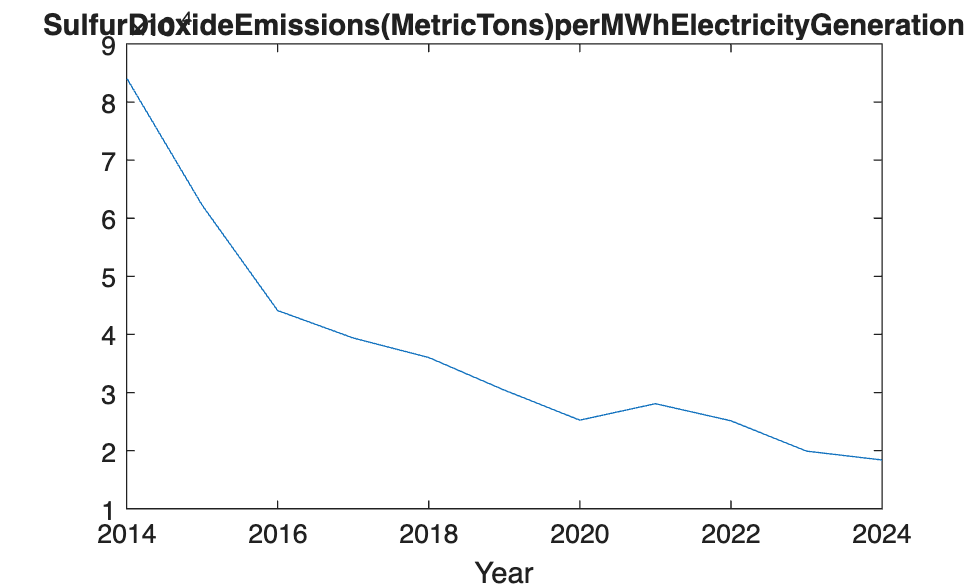

plot(Years,SulfurDioxideEfficiency)

xlabel('Year')
title('SulfurDioxideEmissions(MetricTons)perMWhElectricityGeneration')

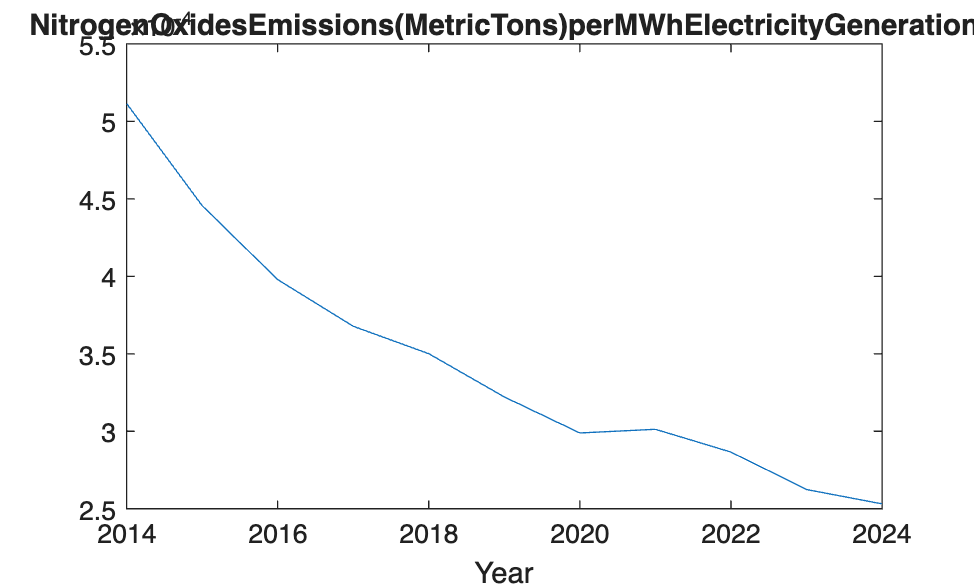

plot(Years,NitrogenOxidesEfficiency)

xlabel('Year')
title('NitrogenOxidesEmissions(MetricTons)perMWhElectricityGeneration')

Not only is each emissions decreasing over the years, it decreasing as the total electricity generated is actually increasing, and so there is we see the emissions per MWh generated is massively decreasing 

This means that the environmental harm may be getting less and less. It is becoming more efficient.